# Forgetting Factor Recursive Least Squares

clearvars, clc;

## Read Data

data = readmatrix('A1-007-DST-US06-FUDS-25-20120827.xlsx', 'Sheet', 'Sheet1');

## Initialization

Ut = data(:,5)';
I = data(:,4)';
TestTime = data(:,1)';
dt = diff(TestTime);
dt(end+1) = dt(end);
N = length(Ut);

Theta = zeros(6, N);
Lambda = 0.98;
P = eye(6) * 1000;
e = zeros(1, N);

R0 = zeros(1, N);
R1 = zeros(1, N);
R2 = zeros(1, N);
C1 = zeros(1, N);
C2 = zeros(1, N);
Uoc = zeros(1, N);

Theta(:, 1) = zeros(6, 1);

disp("~ Total Data: " + N);

~ Total Data: 24469


## Looping

for k = 3:N
    Phi = [Ut(k-1); Ut(k-2); I(k); I(k-1); I(k-2); 1];
    
    K = (P * Phi) / (Lambda + Phi' * P * Phi);
    Theta(:, k) = Theta(:, k-1) + K * (Ut(k) - Phi' * Theta(:, k-1));
    P = (eye(6) - K * Phi') * P / Lambda;

    % Calculate current R0, R1, R2, C1, C2, Uoc
    th1=Theta(1,k); th2=Theta(2,k);
    th3=Theta(3,k); th4=Theta(4,k);
    th5=Theta(5,k); th6=Theta(6,k);
    
    denom = 1 - th1 - th2;

    a = ( th4 - th3 - th5 ) / (1 + th1 - th2);
    b = dt(k)^2 * (1 + th1 - th2) / (4 * denom);
    c = dt(k)   * (1 + th2)      / denom;
    d = -( th3 + th4 + th5 ) / denom;
    f = dt(k)   * (th5 - th3)    / denom;

    tau1 = (c + sqrt(c^2 - 4*b))/2;
    tau2 = (c - sqrt(c^2 - 4*b))/2;

    R0(k)    = a;
    R1(k)    = ( tau1*(d - a) + a*c - f ) / ( tau1 - tau2 );
    R2(k)    = d - a - R1(k);
    C1(k)    = tau1 / R1(k);
    C2(k)    = tau2 / R2(k);
    Uoc(k)  = th6 / denom;

    if k > 100
        mu0  = mean( R0(k-100 : k-1) );
        si0  =  std( R0(k-100 : k-1) );
        mu1  = mean( R1(k-100 : k-1) );
        si1  =  std( R1(k-100 : k-1) );
        mu2  = mean( R2(k-100 : k-1) );
        si2  = std(  R2(k-100 : k-1) );
        muC1 = mean( C1(k-100: k-1) );
        siC1 =  std( C1(k-100: k-1) );
        muC2 = mean( C2(k-100: k-1) );
        siC2 =  std( C2(k-100: k-1) );
        
        lo0  = max(mu0  - 3*si0, 0);  hi0  = mu0  + 3*si0;
        lo1  = max(mu1  - 3*si1, 0);  hi1  = mu1  + 3*si1;
        lo2 = max(mu2 - 3*si2, 0);    hi2 = mu2 + 3*si2;
        loC1 = max(muC1 - 3*siC1,0);  hiC1 = muC1 + 3*siC1;
        loC2 = max(muC2 - 3*siC2,0);  hiC2 = muC2 + 3*siC2;
        
        clR0  = min(max(R0(k),  lo0),  hi0);
        clR1  = min(max(R1(k),  lo1),  hi1);
        clC1  = min(max(C1(k),  loC1), hiC1);
        clC2  = min(max(C2(k),  loC2), hiC2);
        
        if clR0~=R0(k) || clR1~=R1(k) || clC1~=C1(k) || clC2~=C2(k)
            bestError = Inf;
            bestTheta = Theta(:, k);
            
            for n = 0:40
                pastTheta = Theta(:, k-n);
                currentError = abs(Ut(k) - Phi' * pastTheta);
                
                if currentError < bestError
                    bestTheta = pastTheta;
                    bestError = currentError;
                    
                    if currentError < 0.05
                        break
                    end
                end
            end
            
            Theta(:, k) = bestTheta;

            th1=bestTheta(1); th2=bestTheta(2);
            th3=bestTheta(3); th4=bestTheta(4);
            th5=bestTheta(5); th6=bestTheta(6);
            
            denom = 1 - th1 - th2;
            a     = (th4 - th3 - th5) / (1 + th1 - th2);
            b     = dt(k)^2 * (1 + th1 - th2) / (4 * denom);
            c     = dt(k)   * (1 + th2)      / denom;
            d     = -(th3 + th4 + th5) / denom;
            f     = dt(k)   * (th5 - th3)    / denom;
            
            tau1 = (c + sqrt(c^2 - 4*b)) / 2;
            tau2 = (c - sqrt(c^2 - 4*b)) / 2;
            
            R0(k)   = a;
            R1(k)   = ( tau1*(d - a) + a*c - f ) / (tau1 - tau2);
            R2(k)   = d - a - R1(k);
            C1(k)   = tau1 / R1(k);
            C2(k)   = tau2 / R2(k);
            Uoc(k)  = th6 / (1 - th1 - th2);
        end
    end
end

## Graphing Data

figure('Name','Estimated Battery Parameters','NumberTitle','off');
set(gcf,'Position',[100, 100, 1500, 800]);

% Baris 1: R0, R1, R2
subplot(2,3,1);
plot(TestTime, R0);
title('Estimated R_0 (\Omega)');
xlabel('t(s)'); ylabel('R_0'); grid on;

subplot(2,3,2);
plot(TestTime, R1);

title('Estimated R_1 (\Omega)');
xlabel('t(s)'); ylabel('R_1'); grid on;

subplot(2,3,3);
plot(TestTime, R2);

title('Estimated R_2 (\Omega)');
xlabel('t(s)'); ylabel('R_2'); grid on;

subplot(2,3,4);
plot(TestTime, C1);

title('Estimated C_1 (F)');
xlabel('t(s)'); ylabel('C_1'); grid on;

subplot(2,3,5);
plot(TestTime, C2);

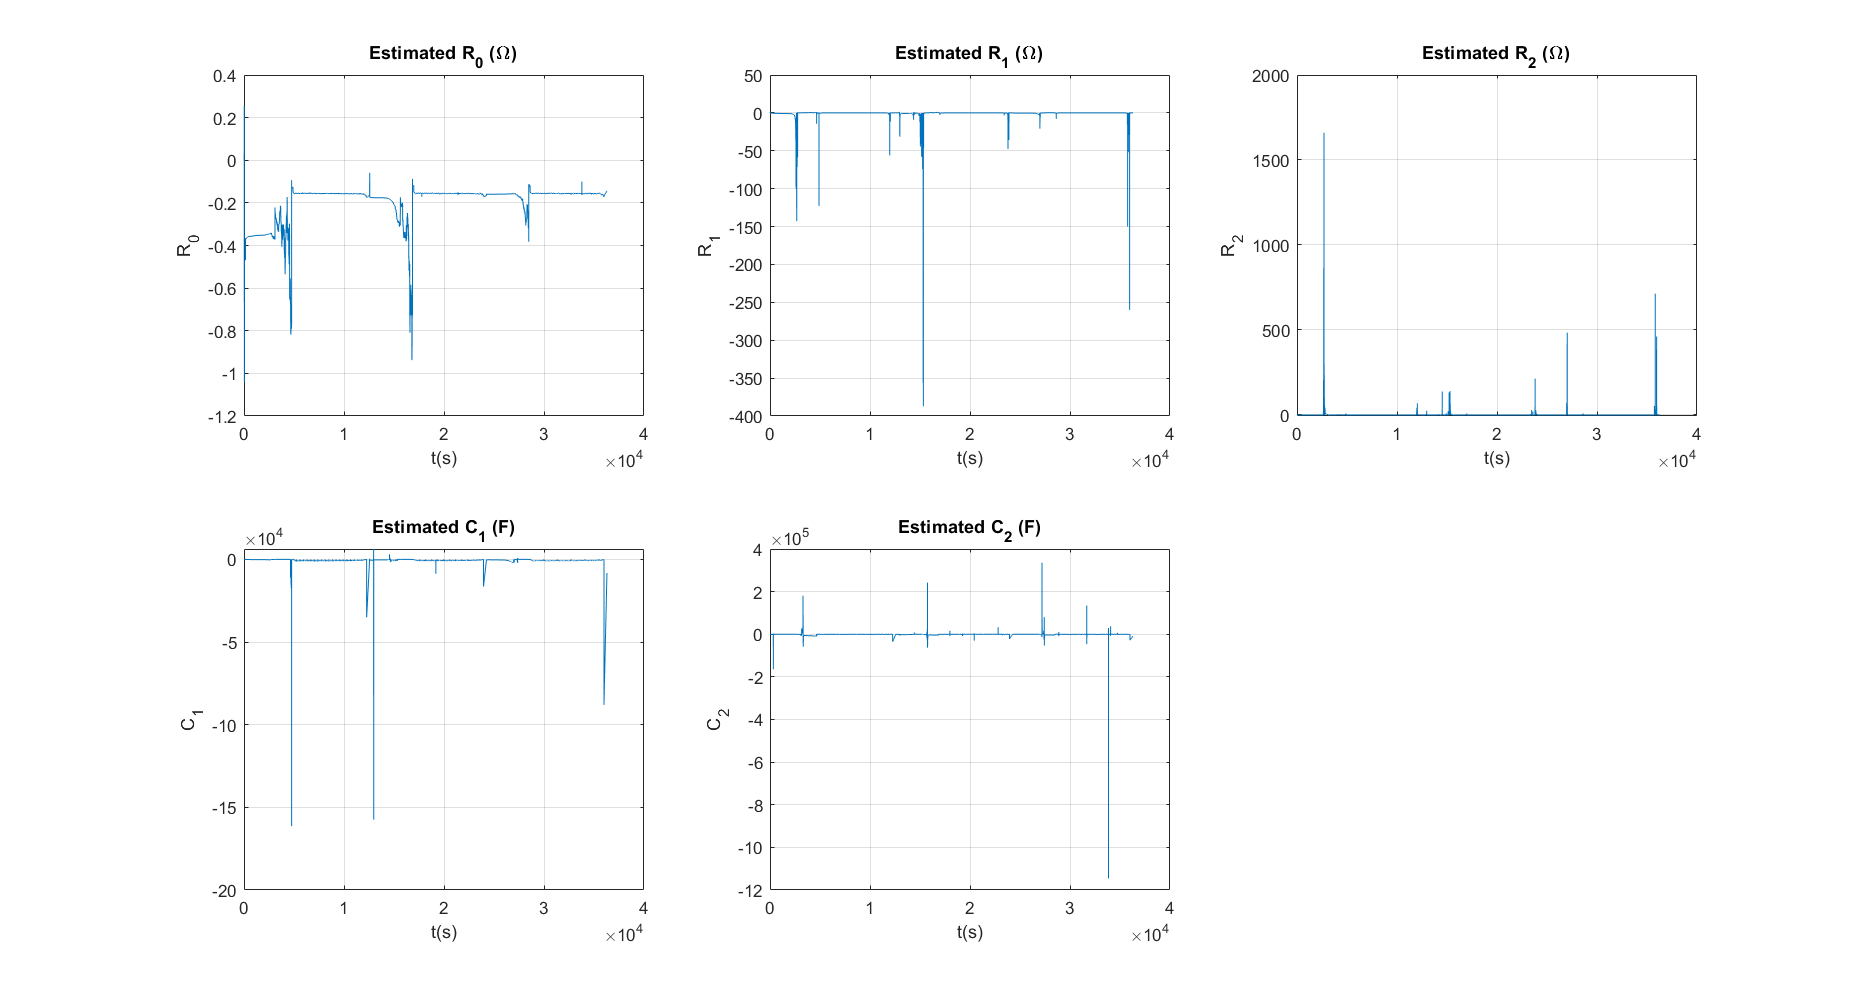

title('Estimated C_2 (F)');
xlabel('t(s)'); ylabel('C_2'); grid on;

## Graphing Data (Cont.)

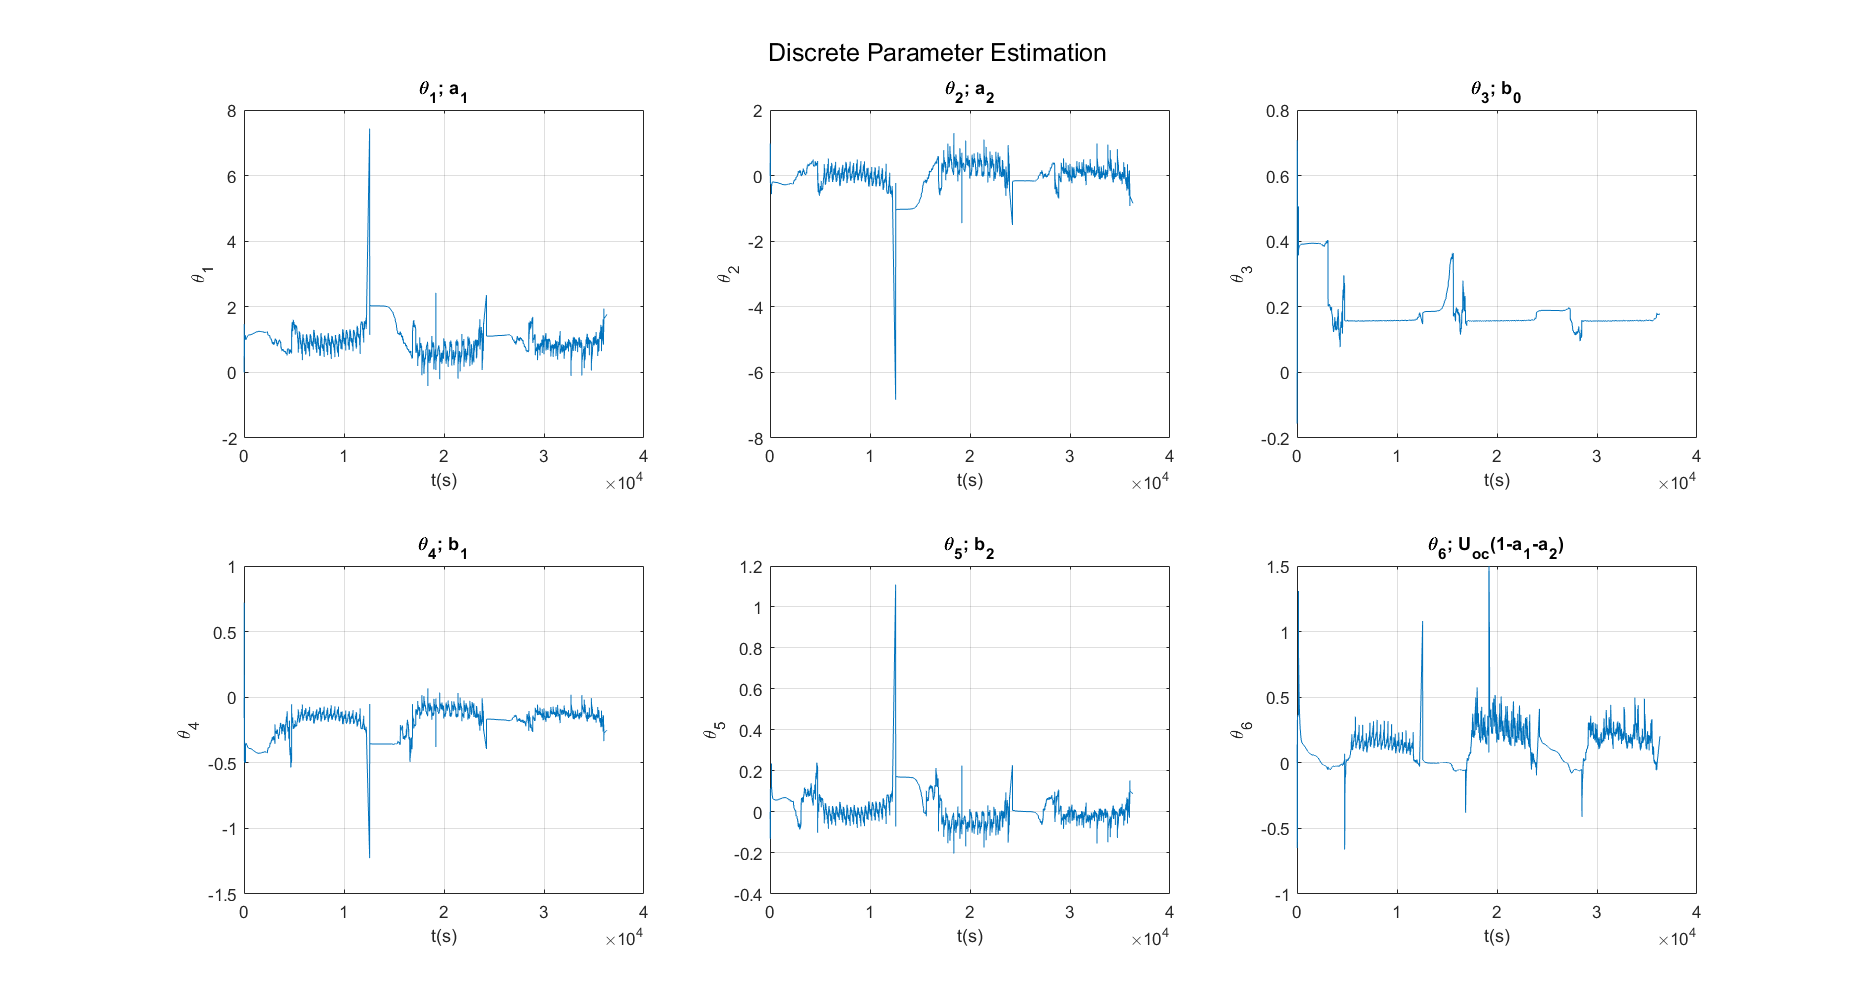

figure;
sgtitle('Discrete Parameter Estimation');
set(gcf,'Position',[100, 100, 1500, 800]);

subplot(2,3,1);
plot(TestTime, Theta(1,:));
title('\theta_1; a_1');
xlabel('t(s)'); ylabel('\theta_1'); grid on;
subplot(2,3,2);
plot(TestTime, Theta(2,:));
title('\theta_2; a_2');
xlabel('t(s)'); ylabel('\theta_2'); grid on;

subplot(2,3,3);
plot(TestTime, Theta(3,:));
title('\theta_3; b_0');
xlabel('t(s)'); ylabel('\theta_3'); grid on;

subplot(2,3,4);
plot(TestTime, Theta(4,:));
title('\theta_4; b_1');
xlabel('t(s)'); ylabel('\theta_4'); grid on;

subplot(2,3,5);
plot(TestTime, Theta(5,:));
title('\theta_5; b_2');
xlabel('t(s)'); ylabel('\theta_5'); grid on;

subplot(2,3,6);
plot(TestTime, Theta(6,:));
title('\theta_6; U_{oc}(1-a_1-a_2)');
xlabel('t(s)'); ylabel('\theta_6'); grid on;

## Graphing Data (Cont.)

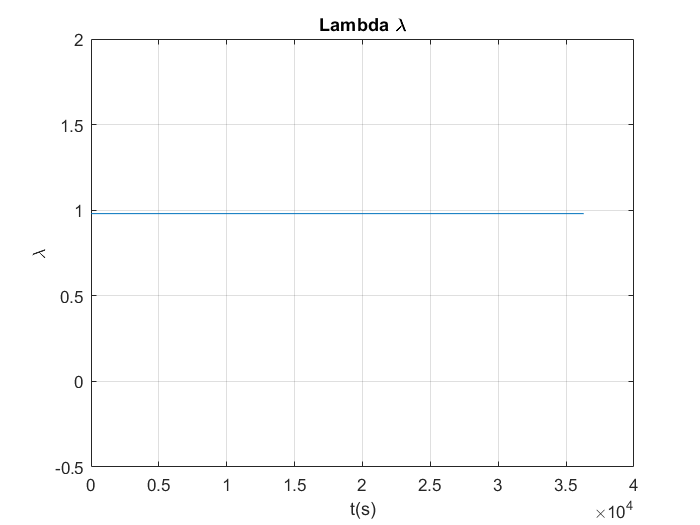

figure;
plot(TestTime, Lambda * ones(N, 1));
title('Lambda \lambda');
xlabel('t(s)'); ylabel('\lambda'); grid on;

## Save the Values

params = [R0', R1', R2', C1', C2', Uoc'];

fileID = fopen('_FFRLSParameters.txt','w');
fprintf(fileID, 'R0\tR1\tR2\tC1\tC2\tUoc\n');

for i = 1:size(params,1)
    fprintf(fileID, '%.6f\t%.6f\t%.6f\t%.6f\t%.6f\t%.6f\n', params(i,1), params(i,2), params(i,3), params(i,4), params(i,5), params(i,6));
end

fclose(fileID);

fileID = fopen('_discreteParameters.txt','w');
fprintf(fileID, 'a1\ta2\tb0\tb1\tb2\tt1\n');

for i = 1:N
    fprintf(fileID, '%.6f\t%.6f\t%.6f\t%.6f\t%.6f\t%.6f\n', Theta(1,i), Theta(2,i), Theta(3,i), Theta(4,i), Theta(5,i), Theta(6,i));
end

fclose(fileID);